# 'wire_box' method usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

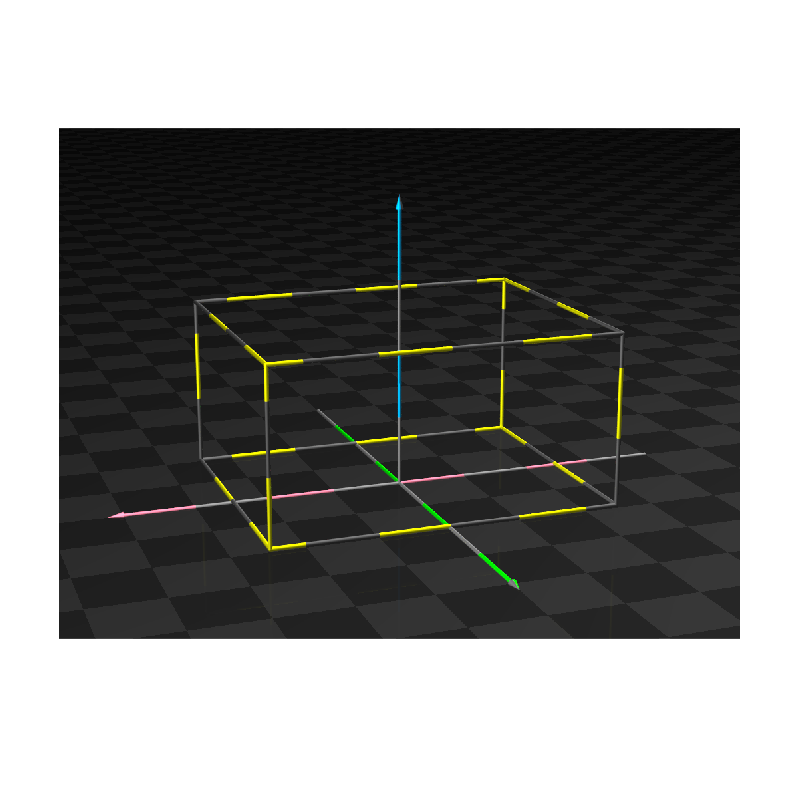

pl.scene_begin('scene_file', 'wire_box.pov', 'image_file', 'wire_box.png');
    pl.include("shapes");
    
    % Camera
    pl.camera('angle', 25, 'location', [4 11 4]*1.8, 'look_at', [0 0 1.5], 'type', 'perspective');

    % Lighgs
    pl.light('location', [10 10 7],     'color', [3 3 3], 'shadowless', true);
    pl.light('location', [-10 10 30],   'color', [3 3 3], 'shadowless', true);
    pl.light('location', [100 200 300], 'color', [1 1 1], 'shadowless', true);
   
    % Textures
    finish = "phong 1 reflection {0.3 metallic 0.8}";
    tex_floor  = pl.declare("tex_floor",        pl.texture('pigment_odd', [0.01 0.01 0.01], 'pigment_even', [0.02 0.02 0.02], 'finish', "phong 1 reflection {0.02 metallic 0.8}"));
    tex_gray   = pl.declare("tex_gray",         pl.texture('pigment', [0.2 0.2 0.2]));
    tex_pink   = pl.declare("tex_plane_pink",   pl.texture('pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.8 0.2 0.3], 'finish', finish));
    tex_yellow = pl.declare("tex_plane_yellow", pl.texture('pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.8 0.8 0],   'finish', finish));
    tex_green =  pl.declare("tex_green",        pl.texture('pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.0 0.8 0],   'finish', finish));
    tex_blue  =  pl.declare("tex_blue",         pl.texture('pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.0 0.4 0.8], 'finish', finish));

    % Axis
    pl.axis('length', [4 4 4], 'radius', 0.025, 'tex_common', tex_gray, 'tex_x', tex_pink, 'tex_y', tex_green, 'tex_z', tex_blue);
    
    % Floor
    pl.plane('normal', [0,0,1], 'texture', tex_floor);

    % Box
    pl.wire_box('llf_corner', [-2.5 -2 0], 'urb_corner', [2.5 2 2.5], 'radius', 0.03, 'texture', tex_yellow);

pl.scene_end();

image = pl.render();
imshow(image);

#### Elapsed time

toc

Elapsed time is 2.788641 seconds.
